clear;
load('C:\Users\Kikki\Archive\dataset\DC_mall\dc');

img = double(image);
x = 51;
y = 601;
cut_image = img(:,y:y+199,x:x+199);

% min(a,[],dim) 
% return the minimum value in the dimension range specified by dim in a
tmp_min = min(min(cut_image, [], 2), [], 3);
tmp_min = repmat(tmp_min, [1 200 200]);
cut_image = cut_image - tmp_min;

tmp_max = max(max(cut_image, [], 2), [], 3);
tmp_max = repmat(tmp_max, [1 200 200])

tmp_max = tmp_max(:,:,1) =

        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468        5468

cut_image = cut_image ./ tmp_max;
image = cut_image;

image_noisy = image + randn(size(cut_image))*(100/255);
image_noisy(image_noisy < 0) = 0;
image_noisy(image_noisy > 1) = 1;
save('denoising.mat','image','image_noisy');

image = permute(cut_image, [2 3 1])

image = image(:,:,1) =

    0.1712    0.1770    0.1876    0.1898    0.2054    0.1913    0.1876    0.1950    0.2154    0.1929    0.2019    0.1812    0.2326    0.2818    0.3094    0.2176    0.2489    0.2723    0.2056    0.1946    0.2138    0.2123    0.2399    0.2118    0.2434    0.2429    0.2546    0.2511    0.2423    0.2306    0.2763    0.3034    0.2659    0.2436    0.3036    0.1743    0.2456    0.2842    0.1191    0.0856    0.0750    0.0730    0.1639    0.1331    0.1357    0.1172    0.1598    0.1456    0.1571    0.0916    0.0856    0.3230    0.4905    0.4592    0.5020    0.4228    0.1412    0.0770    0.1668    0.1410    0.2396    0.4193    0.4106    0.4409    0.4596    0.2529    0.4371    0.2125    0.3007    0.0966    0.1125    0.0914    0.1271    0.1589    0.1754    0.1677    0.2323    0.3050    0.2666    0.2485    0.2052    0.2765    0.2473    0.2052    0.2553    0.2418    0.1904    0.1249    0.1377    0.1242    0.1606    0.1149    0.1569    0.1509    0.1770    0.1315    0.1474    0.

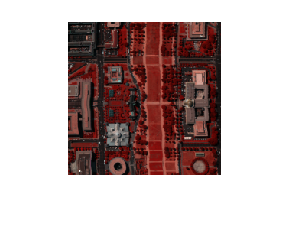

imshow(cat(3,image(:,:,57),image(:,:,27),image(:,:,17)))

p = psnr(double(pred_avg),image(:,:,1:191));

函数或变量 'pred_avg' 无法识别。

s = ssim(double(pred_avg),image(:,:,1:191));

fprintf('psnr: %f, ssim: %f  \n', p, s);
figure; imshow(cat(3,pred_avg(:,:,57),pred_avg(:,:,27),pred_avg(:,:,17)));

imwrite(cat(3,pred_avg(:,:,57),pred_avg(:,:,27),pred_avg(:,:,17)),'3D1.png');